# Grafik Örnekleri

Bir aracın konum, hız ve ivme grafiğini tek bir pencerede çizdiriniz.

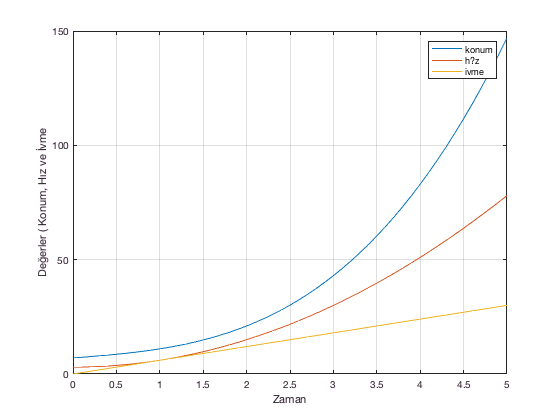

t=0:0.1:5;
x=t.^3+3.*t+7;      %arabanın konumu
v=3.*t.^2+3;        %konumun türevi, hız
a=6.*t;             %hızın türevi, ivme
plot(t,x,t,v,t,a);  %t,x : araban?n konum de?i?im grafi?i
xlabel('Zaman');
ylabel('Değerler ( Konum, Hız ve İvme');
legend('konum','hız','ivme');   %?izilen grafikteki renklerin anlam?n? yazar.
grid on

her birisini ayrı bir pencerede çizdiriniz.

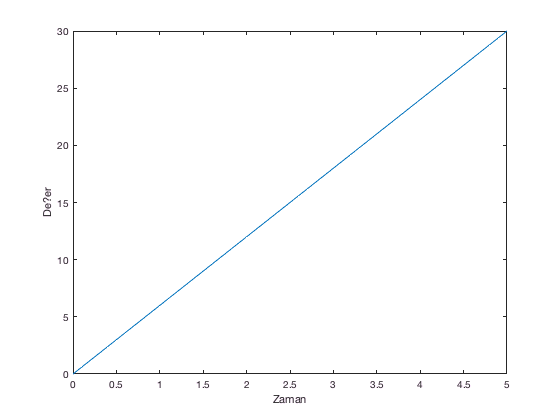

figure(1), plot(t,x);
figure(2), plot(t,v);
figure(3),plot(t,a);
xlabel('Zaman');
ylabel('De?er');

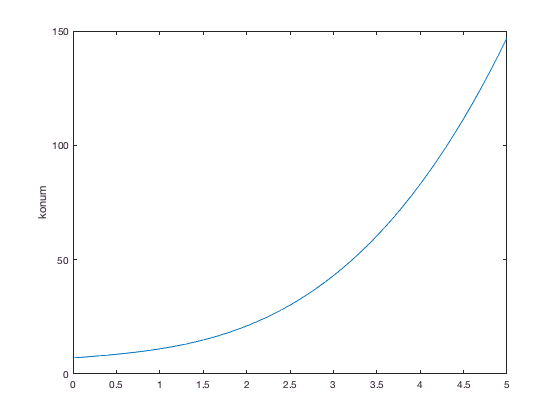

figure(1), ylabel('konum');

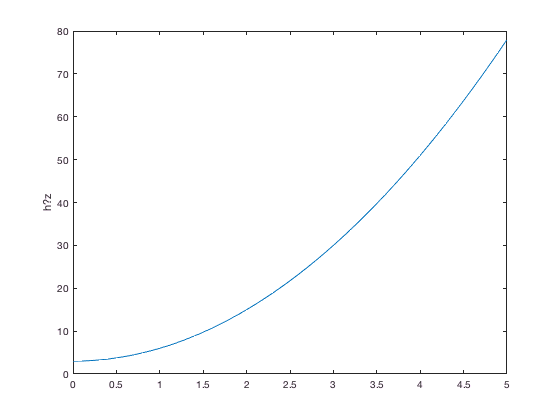

figure(2),ylabel('h?z');

x =-10:0.1:10;
y = x.^2;
plot(x,y);
title('y= x^2 Grafi?i');
grid;

text(2,50,'1.B?lge')
text(7,35,'2.B?lge')

gtext('1. B?lge')




x=0:pi/40:4*pi;
y=sin(x);
z=cos(x);
t=tan(x);
subplot(3,4,1);
plot(x,y);
title('sinx fonksiyonu');
subplot(3,4,2);
plot(x,z);
title('cosx fonksiyonu');
subplot(3,4,3);
plot(x,t);
title('tanx fonksiyonu');

hold on 
x=0:pi/40:4*pi;
y=sin(x);
plot(x,y,'-r');  % birinci plot

plot(x,cos(x),'-k');   % ikinci plot
y2=exp(2*sin(x));
plot(x,y2,'-g');    %???nc? plot



İki tane y eksenine ihtiyaç varsa plotyy komutunu kullanmamız gerekir.

yyaxis komutu tavsiye edilmektedir. 

%plotyy
% 2008-2014 ki?ine ba??na d??en milli gelir ile n?fus gra?ini ?izdiriniz.
x  = 2008:2014;
y1 = [70000000 71000000 72000000 73000000 74000000 75000000 76000000];
y2 = [5000 10000 7200 12300 6400 5500 3600 ];

[hAx,hCizgi1,hCizgi2] = plotyy(x,y1,x,y2)
legend('N?fus Art???','Ki?i Ba?? Milli Gelir');

plotyy(x,y1,x,y2)
legend('N?fus Art???','Ki?i Ba?? Mili Gelir','Location','eastoutside');

title('Y?llara g?re n?fus  ve ki?i ba??ona d??en milli gelir');
ylabel(hAx(1),'N?fus (Milyon) ');
ylabel(hAx(2),'Ki?i Ba??na D??en Milli Gelir (x1000) ');
xlabel('Y?llar');


# Plot3 komutu

% Matlab ortam?nda ayn?  uzunlukta ?? vekt?r?n birbirlerine g?re olan de?i?imleri 3-boyutlu bir grafik ?zerinde plot3(x,y,z) komutu ile ?l??lebilir.

% ?rnek:

clc; %clear console
clear all; % workspace deki tüm değişkenleri siler.
close all; % figure pencerelerini kapatır.
x=0:0.1:5

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


a=length(x)

a = 51

y(1:a)=2

y =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


z=exp(cos(x))

z =     2.7183    2.7047    2.6646    2.5995    2.5120    2.4051    2.2826    2.1487    2.0071    1.8619    1.7165    1.5740    1.4367    1.3067    1.1853    1.0733    0.9712    0.8791    0.7968    0.7238    0.6596    0.6036    0.5552    0.5136    0.4784    0.4488    0.4245    0.4049    0.3898    0.3787    0.3716    0.3682    0.3685    0.3725    0.3803    0.3920    0.4079    0.4282    0.4534    0.4839    0.5201    0.5628    0.6125    0.6698    0.7354    0.8099    0.8939    0.9877    1.0914    1.2050


plot3(x,y,z,'-r','linewidth',5);
xlabel('x');
ylabel('y');
zlabel('z');
grid on 


scatter verilen x,y noktalar?na kar??l?k grafik ekranda bir nokta ?izer.

% -100 ile 100 aras?nda 100 tane rastgele say? ?retip scatter ile

% grafi?ini ?izdiriniz.

for adim=1:100
    x=randi([-100,100],100,1);
    y=randi([-100,100],100,1);
    hold off;
    scatter(x,y);
    pause(0.2);
end

for adim=1:100
    x=randi([-100,100],100,1);
    y=randi([-100,100],100,1);
    z=randi([-100,100],100,1);
    scatter3(x,y,z,'MarkerFaceColor','b','MarkerEdgeColor','k');
    xlabel('x ekseni');ylabel('y ekseni');zlabel('z ekseni');
    pause(0.2);
end

repmat([ 1 2 3] , 3, 1 )

y = -10:0.5:10;
x = -10:0.5:10;
[X, Y] = meshgrid(x, y);
Z = sin(sqrt(X.^2+Y.^2)) ./ sqrt(X.^2+Y.^2);
surfc(X, Y, Z);
view(-38, 18);
title('3D Matlab Graph');
xlabel('x');
ylabel('y');
zlabel('z');


% rastgele ?retilmi? de?erlerin histogram?n?n ?izilmesi.
x=randn(10000,1)*3;
hist(x)


$$\theta$$


ylabel('sin(\Theta)')

figure(2);
a= 0:0.01:2*pi;
plot(a,sin(a));


$$$$


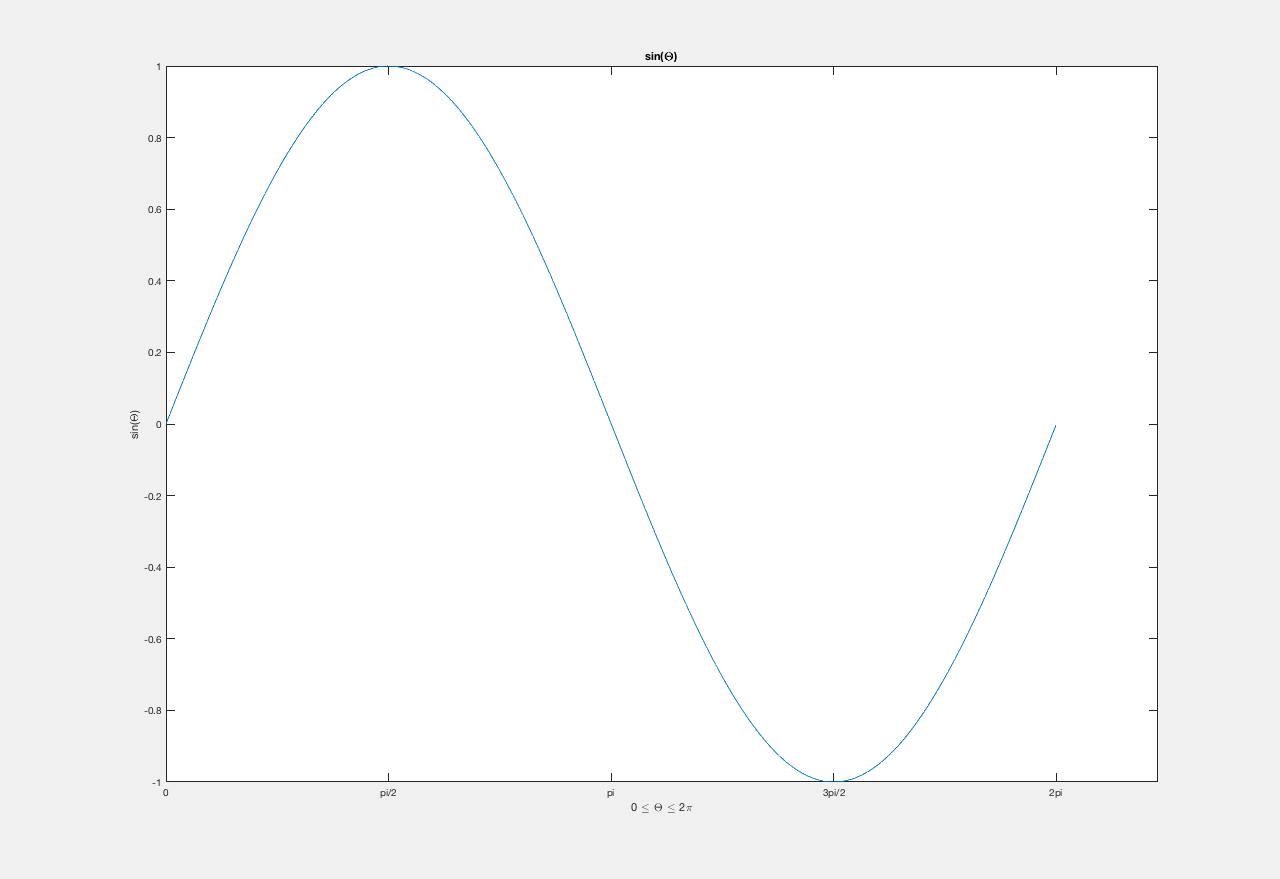

% set(gca,'XLim',[-7 14]);
set(gca,'XTick',0:pi/2:2*pi)
set(gca,'XTickLabel',{'0','pi/2','pi','3pi/2','2pi'})

xlabel('0 \leq \Theta \leq 2\pi')
ylabel('sin(\Theta)')
title('sin(\Theta)')